## Material Properties

close all;
clear;

% Matboard dimensions (from in to mm)
matboard_w = 32 * 25.4

matboard_w = 812.8000

matboard_h = 40 * 25.4

matboard_h = 1016

matboard_t = 0.05 * 25.4

matboard_t = 1.2700


% Matboard properties
sigma_tens = 30

sigma_tens = 30

sigma_comp = 6

sigma_comp = 6

shear_strength = 4

shear_strength = 4

youngs_modulus = 4000

youngs_modulus = 4000

poissons_ratio = 0.2

poissons_ratio = 0.2000


% Glue properties
shear_strength_glue = 2

shear_strength_glue = 2

## Moment and Shear Envelopes

L = 1200;  % Length of bridge
n = L+1;  % Number of points
P = 400;  % Total weight of train [N]
n_train = L-960+1;  % Number of train locations

lhs_dist = linspace(0, L, n);

% Offset by 1 because MALDLAB indexes with 1
% Offset by 1 more to shift cumsum one left
x_shear_start_locations = [52, 228, 392, 568, 732, 908] + 2;
x_train_loads = [-P/6, -P/6, -P/6, -P/6, -P/6, -P/6];
start_shear_all = (720-(0:1:n_train-1)')/3;  % Column vector of all possible starting shears
all_train_locations = zeros(n_train, n);

for i = 0:n_train-1
    all_train_locations(i+1, x_shear_start_locations+i) = x_train_loads;
end

% Each row is an SFD for each train location
all_shear = zeros(n_train, n);
all_shear(:,1) = start_shear_all;
all_shear = all_shear + all_train_locations;
all_shear = cumsum(all_shear, 2);

% Each row is a BMD for each train location
all_moment = cumsum(all_shear, 2);
all_moment = all_moment - start_shear_all;

x = 76  % Location of the train (not needed anymore)

x = 76


% Shear and moment envelopes
shear_envelope = max(abs(all_shear))

shear_envelope =    240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240


moment_envelope = max(all_moment)

moment_envelope = 1.0e+04 *

         0    0.0240    0.0480    0.0720    0.0960    0.1200    0.1440    0.1680    0.1920    0.2160    0.2400    0.2640    0.2880    0.3120    0.3360    0.3600    0.3840    0.4080    0.4320    0.4560    0.4800    0.5040    0.5280    0.5520    0.5760    0.6000    0.6240    0.6480    0.6720    0.6960    0.7200    0.7440    0.7680    0.7920    0.8160    0.8400    0.8640    0.8880    0.9120    0.9360    0.9600    0.9840    1.0080    1.0320    1.0560    1.0800    1.1040    1.1280    1.1520    1.1760


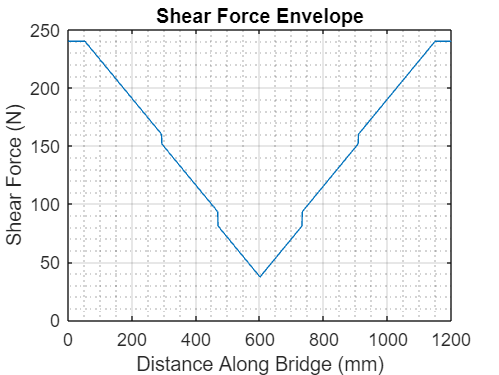


figure
plot(lhs_dist, shear_envelope)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Absolute Shear Force Envelope")

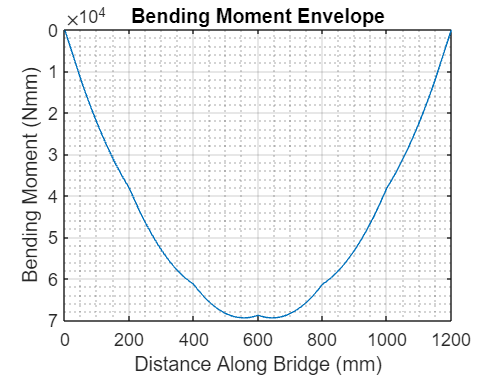


figure
plot(lhs_dist, moment_envelope)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Envelope")

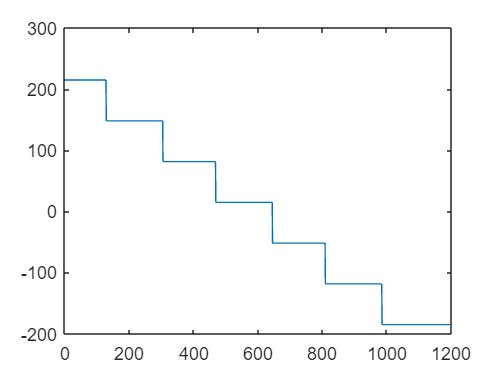

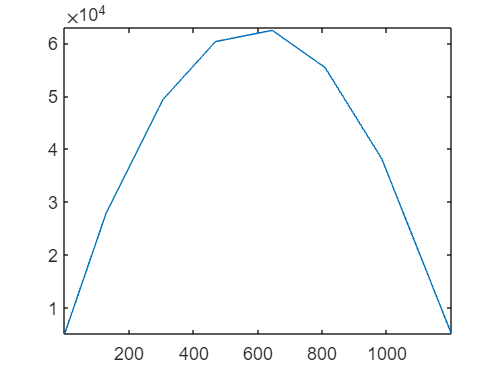


% If querying x_shear and x_moment is required
% x_shear = all_shear(x+1,:);
% x_moment = all_moment(x+1,:);

## Bridge Geometry

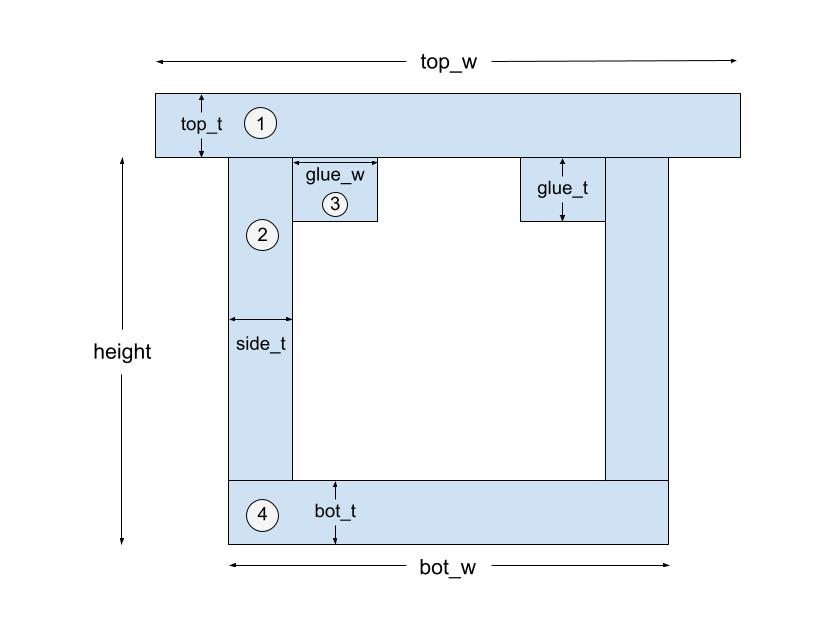

% Define params
top_w = 100;
bot_w = 80;  % modified
height = 75; % defined from lowest point without including thickness of the top area
top_t = 1.27;  % modified
bot_t = 1.27;
side_t = 1.27;
glue_w = 5; % not including thickness of side
glue_t = 1.27;

## Cross-Sectional Properties

% Calculate y bar, I, Q_glue, Q_cent
area_1 = top_t * top_w;
area_2 = (height-bot_t) * side_t;
area_3 = glue_w * glue_t;
area_4 = bot_t * bot_w;

y1 = height + top_t/2;
y2 = (height+bot_t) / 2;
y3 = height - glue_t/2;
y4 = bot_t/2;

I1 = top_w*(top_t^3) / 12;
I2 = side_t*((height-bot_t)^3) / 12;
I3 = glue_w*(glue_t^3) / 12;
I4 = bot_w*(bot_t^3) / 12;

tot_area = area_1 + 2*area_2 + 2*area_3 + area_4;

y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4) / tot_area

y_bar = 41.4311


d1 = y1 - y_bar;
d2 = y2 - y_bar;
d3 = y3 - y_bar;
d4 = y4 - y_bar;

sec1 = area_1*(d1^2) + I1;
sec2 = 2 * (area_2*(d2^2) + I2);
sec3 = 2 * (area_3*(d3^2) + I3);
sec4 = area_4*(d4^2) + I4;

I = sec1 + sec2 + sec3 + sec4

I = 4.1835e+05


Q_cent = (bot_w-2*side_t)*bot_t*(y_bar-bot_t/2) + 2*y_bar*side_t*(y_bar/2)

Q_cent = 6.1933e+03

Q_glue = area_1 * (height-y_bar + 1.27/2)

Q_glue = 4.3439e+03

Non-thin plate stresses due to train

% Maximum abs(shear value) and abs(moment value)
[shear_max, shear_max_index] = max(shear_envelope);
[moment_max, moment_max_index] = max(moment_envelope);

% Largest tensile and compressive stress
sigma_top_tens = -moment_envelope * (height+top_t-y_bar)/I

sigma_top_tens =          0   -0.0200   -0.0400   -0.0600   -0.0799   -0.0999   -0.1199   -0.1399   -0.1599   -0.1799   -0.1999   -0.2198   -0.2398   -0.2598   -0.2798   -0.2998   -0.3198   -0.3398   -0.3598   -0.3797   -0.3997   -0.4197   -0.4397   -0.4597   -0.4797   -0.4997   -0.5196   -0.5396   -0.5596   -0.5796   -0.5996   -0.6196   -0.6396   -0.6595   -0.6795   -0.6995   -0.7195   -0.7395   -0.7595   -0.7795   -0.7995   -0.8194   -0.8394   -0.8594   -0.8794   -0.8994   -0.9194   -0.9394   -0.9593   -0.9793


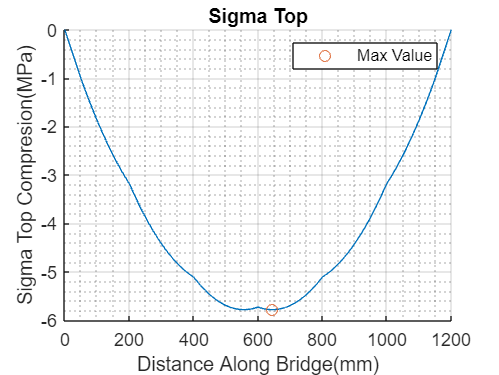

sigma_bot_compress = moment_envelope * y_bar/I;

% Largest shear stress at the centroidal axis
T_cent = (shear_envelope*Q_cent) / (I*(2*side_t));

% Largest shear stress at glue joints
T_glue = (shear_envelope*Q_glue) / (I*(2*glue_w));

%graph for sigma top
figure
hold on
plot(lhs_dist,sigma_top_tens)
plot(moment_max_index,sigma_top_tens(moment_max_index),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma Top Compresion(MPa)")
title("Sigma Top")
grid on
grid minor
legend("","Max Value")

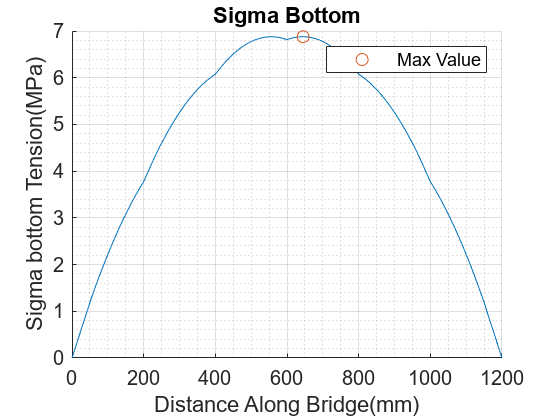

figure

%graph for sigma bottom
hold on
plot(lhs_dist,sigma_bot_compress)
plot(moment_max_index,sigma_bot_compress(moment_max_index),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma bottom Tension(MPa)")
grid on
grid minor
legend("","Max Value")
title("Sigma Bottom")

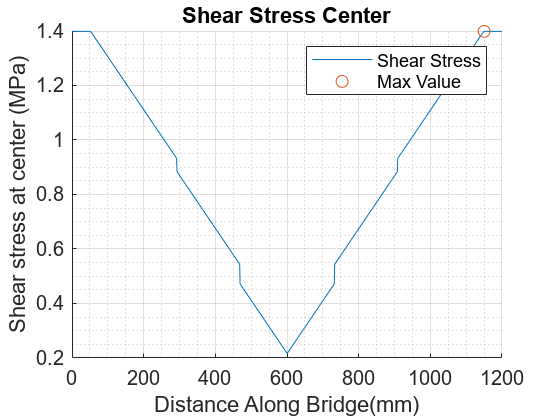

figure
%graph for shear stress at center
hold on
plot(lhs_dist,T_cent)
plot(shear_max_index, T_cent(shear_max_index),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear stress at center (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Center")

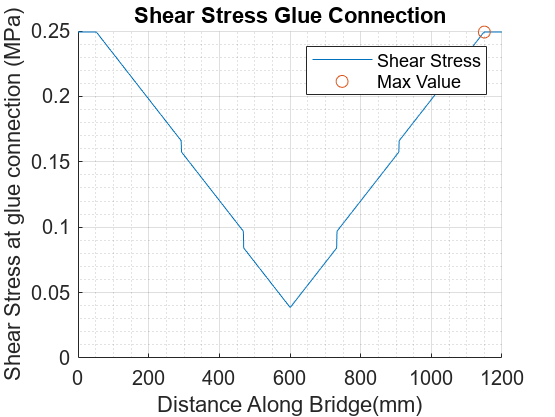

figure

%graph for shear stress at glue connection
hold on
plot(lhs_dist,T_glue)
plot(shear_max_index, T_glue(shear_max_index),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Stress at glue connection (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Glue Connection")

figure

## Thin Plate

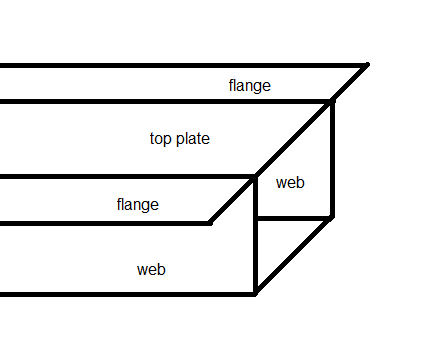

% Thin plate buckling

% Case 1: Bucking of the top plate due to flexural stresses
t_top_plate = top_t

t_top_plate = 1.2700

b_in = bot_w - side_t

b_in = 78.7300

stress_top_plate = (4*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_top_plate/b_in)^2

stress_top_plate = 3.5669


% Case 2: Buckling of the flanges due to flexural stresses
t_flange = top_t

t_flange = 1.2700

b_out = (top_w-bot_w)/2 + side_t/2

b_out = 10.6350

stress_side_flange = (0.425*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_flange/b_out)^2

stress_side_flange = 20.7696


% Case 3: Buckling of the webs due to flexural compression
t_web_flex = side_t

t_web_flex = 1.2700

y_top = height - y_bar

y_top = 33.5689

stress_varying_shear = (6*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_web_flex/y_top)^2

stress_varying_shear = 29.4301


% Case 4: Shear buckling
t_web_shear = side_t

t_web_shear = 1.2700

h_web = height - glue_t/2 - bot_t/2

h_web = 73.7300

a = 400

a = 400

stress_shear_buckle = (5*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * ((t_web_shear/h_web)^2 + (t_web_shear/a)^2)

stress_shear_buckle = 5.2566

## Factor of Safety

FOS_tension = sigma_tens ./ sigma_bot_compress;
FOS_comp = -sigma_comp ./ sigma_top_tens;
FOS_flexbuck1 = -stress_top_plate ./sigma_top_tens;
FOS_flexbuck2 = -stress_side_flange ./ sigma_top_tens;
FOS_flexbuck3 = -stress_varying_shear ./ sigma_top_tens;

FOS_shear = shear_strength ./ T_cent;
FOS_shear_glue = shear_strength_glue ./ T_glue;
FOS_shear_buck = stress_shear_buckle ./ T_cent;


## Shear Force Capacities + Bending Moment Capacities

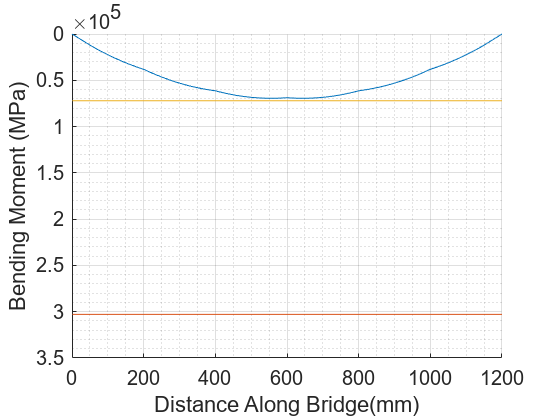

M_fail_tens = FOS_tension .* moment_envelope;
M_fail_comp = FOS_comp .* moment_envelope;
M_fail_buck1 = FOS_flexbuck1 .* moment_envelope;
M_fail_buck2 = FOS_flexbuck2 .* moment_envelope;
M_fail_buck3 = FOS_flexbuck3 .* moment_envelope;

M_fail_shear = FOS_shear .* shear_envelope;
M_fail_shear_glue = FOS_shear_glue .* shear_envelope;
M_fail_shear_buck = FOS_shear_buck .* shear_envelope;

figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_tens)
plot(lhs_dist, M_fail_comp)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
%legend("Bending Moment Diagram", "Matboard Tension Failure", "Matboard Compression Failure")
hold off;

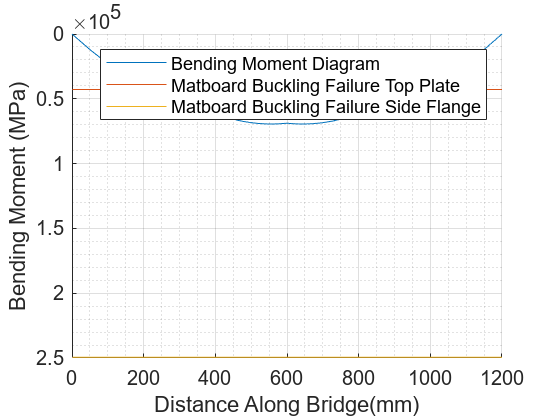


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck1)
plot(lhs_dist, M_fail_buck2)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Top Plate", "Matboard Buckling Failure Side Flange")
hold off;

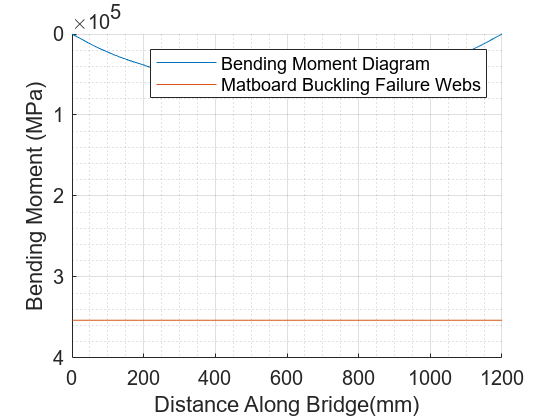


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck3)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Webs")
hold off;

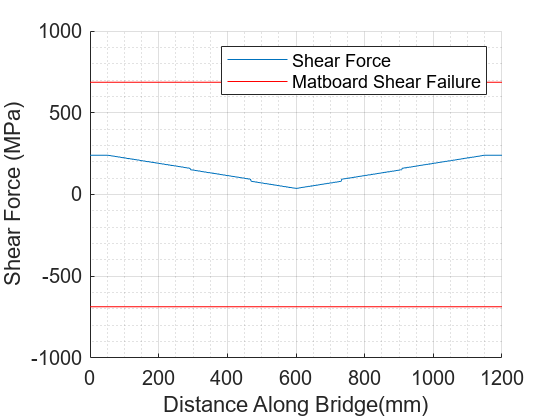


figure
hold on
plot(lhs_dist, shear_envelope)
plot(lhs_dist, M_fail_shear,"r")
plot(lhs_dist, -M_fail_shear,"r")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
legend("Shear Force","Matboard Shear Failure")
hold off

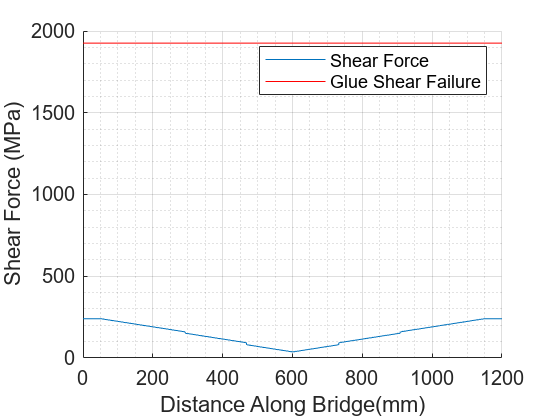




figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, M_fail_shear_glue,"r")
legend("Shear Force","Glue Shear Failure")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off

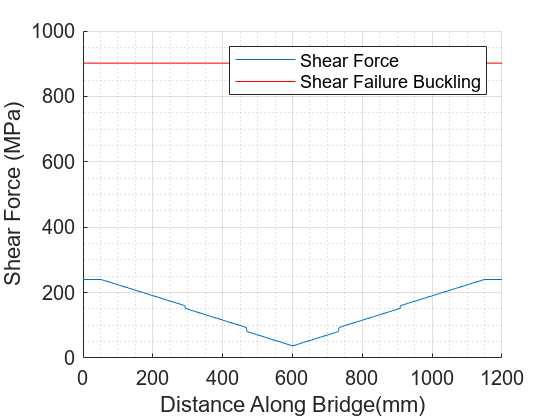


figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, M_fail_shear_buck,"r")
legend("Shear Force","Shear Failure Buckling")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off

min(FOS_tension)

ans = 4.3621

min(FOS_comp)

ans = 1.0375

min(FOS_flexbuck1)

ans = 0.6168

min(FOS_flexbuck2)

ans = 3.5914

min(FOS_flexbuck3)

ans = 5.0889

min(FOS_shear)

ans = 2.8596

min(FOS_shear_glue)

ans = 8.0257

min(FOS_shear_buck)

ans = 3.7579

SA = 1260*(bot_w+top_w+2*(height-bot_t)+2*glue_t)

SA = 4.1580e+05

Surface_area_percent = (1260*(bot_w+top_w+2*(height-bot_t)+2*glue_t))/800000;
Surface_area_percent_left = 1 - Surface_area_percent

Surface_area_percent_left = 0.4802